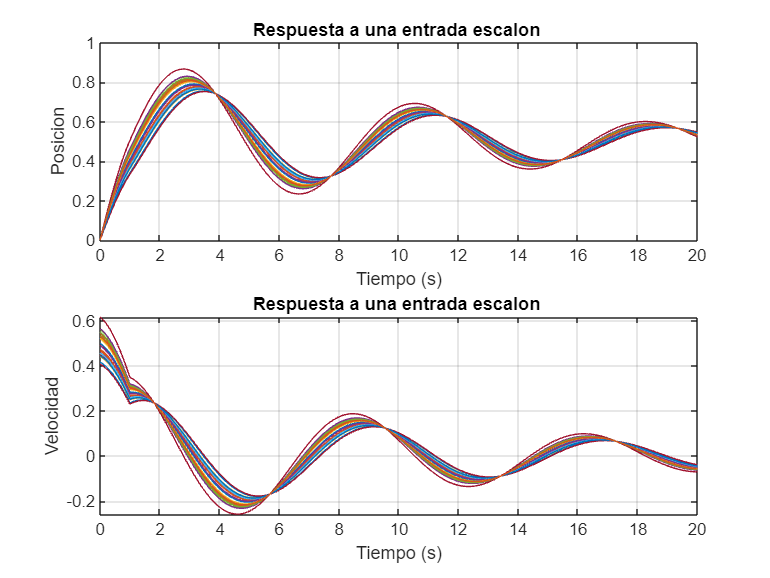

clear all
close all

% Valores nominales de los parámetros
m = 3;
c = .5;
k = 2;

% Número de muestras
num_samples = 30;

% Condiciones iniciales nominales
x0_nominal = 0.5;  % Posición inicial
v0_nominal = 0;  % Velocidad inicial

% Incertidumbre del 10% para las condiciones iniciales
x0_variation = 0.10 * x0_nominal;
v0_variation = 0.10 * v0_nominal;

% Realizar el muestreo de condiciones iniciales
x0_samples = x0_nominal + x0_variation * randn(num_samples, 1);
v0_samples = v0_nominal + v0_variation * randn(num_samples, 1);

% Configuración de la simulación
t = 0:0.01:20;  % Tiempo de simulación

% Inicializar matrices para almacenar las respuestas
x1_responses = zeros(num_samples, length(t));
x2_responses = zeros(num_samples, length(t));


% Asignar valores de los parámetros al modelo en Simulink
set_param('t7_videoclase2_masa_resorte_amortiguador/m', 'Gain', num2str(1/m));
set_param('t7_videoclase2_masa_resorte_amortiguador/c', 'Gain', num2str(c));
set_param('t7_videoclase2_masa_resorte_amortiguador/k', 'Gain', num2str(k));

% Simular cada sistema
for i = 1:num_samples
    % Asignar condiciones iniciales
    x0 = x0_samples(i);
    v0 = v0_samples(i);
    set_param('t7_videoclase2_masa_resorte_amortiguador/Integrator1', 'InitialCondition', num2str(x0));
    set_param('t7_videoclase2_masa_resorte_amortiguador/Integrator2', 'InitialCondition', num2str(v0));

    % Ejecutar la simulación
    simOut = sim('t7_videoclase2_masa_resorte_amortiguador', 'StopTime', num2str(t(end)));

    t = simOut.tout;
    x1_responses(i, :) = simOut.xout(:, 1);
    x2_responses(i, :) = simOut.xout(:, 2);
end

% Mostrar resultados
figure;
subplot(2,1,1);
plot(t, x1_responses);
title('Respuesta a una entrada escalon ');
xlabel('Tiempo (s)');
ylabel('Posicion');
grid on;
subplot(2,1,2);
plot(t, x2_responses);
title('Respuesta a una entrada escalon ');
xlabel('Tiempo (s)');
ylabel('Velocidad');
grid on;